bar = prior

not bar = posterior

## Prediction step

mean:                   $\bar{\mathbf{x}}=\mathbf{F}\mathbf{x}+\mathbf{B}\mathbf{u}$

covariance:         $\bar{\mathbf{P}}=\mathbf{F}\mathbf{P}\mathbf{F}+\mathbf{Q}$

## Update step

residual:               $\mathbf{e}=\mathbf{z}-\mathbf{H}\bar{\mathbf{x}}$

gain:                       $\mathbf{K}=\bar{\mathbf{P}}\mathbf{H}^T(\mathbf{H}\bar{\mathbf{P}}\mathbf{H}^T+\mathbf{R})^{-1}$

mean:                   $\mathbf{x}=\bar{\mathbf{x}}+\mathbf{K}\mathbf{e}$

covariance:         $\mathbf{P}=(\mathbf{I}-\mathbf{K}\mathbf{H})\bar{\mathbf{P}}$

### **Clearing**

clear variables; close all; clc;
addpath('../utilities');
rng(1);

### **Model**

% number of states, usually n
% position and velocity
dim_x = 2;

% number of measures, usually m
% position sensor
dim_z = 1;

% number of control input, usually p
dim_u = 1;

% discrete time step
dt = 0.1;

% state matrix
% Newton equations of motion (constant velocity)
F = [1 dt; 0 1];

% measurement matrix
H = [1 0];

% control input matrix
B = zeros(dim_x, dim_u);

% process noise covariance matrix
% Q = [0.588 1.175; 1.175 2.35];
Q = diag([1e-1 1e-1]);

% measurement noise covariance matrix
R = 1;

% control input
u = 0;

### **Initial conditions**

% initil state (mean)
x0 = [10 5]';

% initial belief of the state (covariance)
P0 = diag([100 100]);

### **Filter settings**

% number of iterations
iterations = 1000;

% preallocate memory
x_posterior = cell(1, iterations);
P_posterior = cell(1, iterations);
x_prior = cell(1, iterations);
P_prior = cell(1, iterations);
S = cell(1, iterations);
residuals = cell(1, iterations);
gains = cell(1, iterations);
true_values = cell(1, iterations);
measures = cell(1, iterations);

### **Compute data**

% starting position and velocity
xs = [0, 2]'; 
% simulation of the process
for tt = 1 : iterations
    % mvnrnd
    xs = F * xs + sqrtm(Q) * randn(dim_x, 1);
    % add something to the model not modeled by the filter
    % xs = F * xs + sqrtm(Q) * randn(dim_x, 1) + 5*sin(2*pi*1*tt*dt);
    true_values{tt} = xs;
    % only position sensor
    measures{tt} = xs(1) + sqrtm(R) * randn(dim_z, 1);
end

### **Filter initialization**

% 1. Initialize the state of the filter
x = x0;

% 2. Initialize our belief in the state
P = P0;

### **Filtering**

for tt = 1 : iterations
    % predict step:
    % 1. Use process model to predict state at the next time step (what we expect) 
    x = F*x + B*u;
    % 2. Adjust belief to account for the uncertainty in prediction   
    P = F*P*F' + Q;
    
    % saving
    x_prior{tt} = x;
    P_prior{tt} = P;
   
    % update step:
    % 1. Get a measurement and associated belief about its accuracy
    z = measures{tt};
    % 2. Compute residual between estimated state and measurement
    e = z - H*x;
    % 3. Compute scaling factor based on whether the measurement or prediction is more accurate
    K = P*H' / (H*P*H' + R);
    S{tt} = H*P*H' + R; % saving
    % 4. set state between the prediction and measurement based on scaling factor
    x = x + K*e;
    % 5. update belief in the state based on how certain we are in the measurement
    % P = P - K*H*P;
    % Joseph equation to reduce numeric errors
    P = (eye(dim_x)-K*H)*P*(eye(dim_x)-K*H)' + K*R*K';
    
    % saving
    x_posterior{tt} = x;
    P_posterior{tt} = P;
    gains{tt} = K;
    residuals{tt} = e;
end

### **Plot**

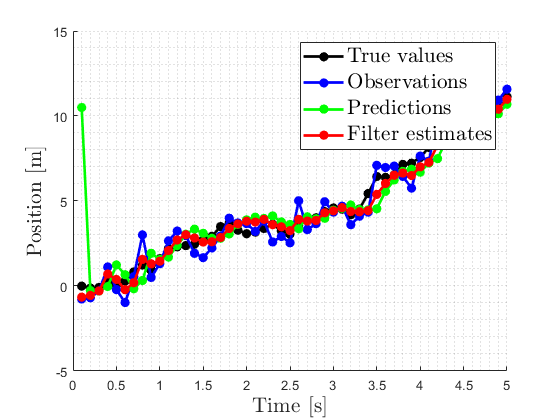

% data
time = (1 : 1 : iterations) * dt;
x_posterior_m = cell2mat(x_posterior);
x_prior_m = cell2mat(x_prior);
z_m = cell2mat(measures);
true_values_m = cell2mat(true_values);
P_posterior_m = cell2mat(P_posterior);
P_prior_m = cell2mat(P_prior);
S_m = cell2mat(S);
gains_m = cell2mat(gains);

% compare position
figure(1); hold on; grid minor;
plot(time, true_values_m(1, :), 'k-o', 'LineWidth', 2, 'MarkerSize', 5, 'MarkerFaceColor', 'k')
plot(time, z_m(1, :), 'b-o', 'LineWidth', 2, 'MarkerSize', 5, 'MarkerFaceColor', 'b')
plot(time, x_prior_m(1, :), 'g-o', 'LineWidth', 2, 'MarkerSize', 5, 'MarkerFaceColor', 'g')
plot(time, x_posterior_m(1, :), 'r-o', 'LineWidth', 2, 'MarkerSize', 5, 'MarkerFaceColor', 'r')
legend('True values', 'Observations', 'Predictions', 'Filter estimates', 'Interpreter', 'latex', 'FontSize', 16)
xlabel('Time [s]', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Position [m]', 'Interpreter', 'latex', 'FontSize', 16);
xlim([0, 5]); ylim([-5, 15]); % custom view
exportgraphics(gcf, 'KFrun.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector')

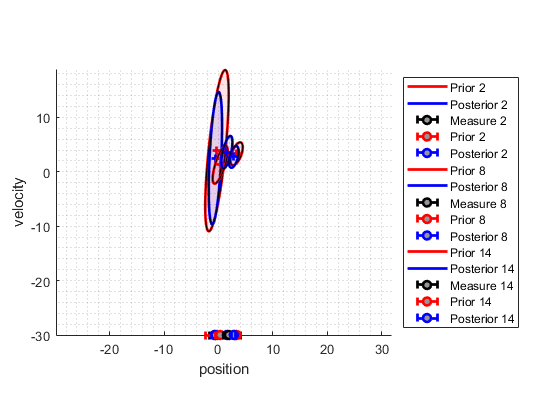

% variance of the position
% figure; hold on; grid minor;
% plot(P_posterior_m(1, 1:2:end))
% variance of the velocity
% figure; hold on; grid minor;
% plot(P_posterior_m(2, 2:2:end))

% Relationship posterior - prior - posterior
figure; hold on; grid minor;
set(gcf, 'DefaultLineLineWidth', 2);
axis equal; xlabel('position'); ylabel('velocity'); legend('location', 'eastoutside');
errorbar_height = -30;
for tt = 2 : 6 : 14
    plot_covariance_ellipse(x_prior_m(:, tt), P_prior_m(:, 2*tt-1:2*tt), 0.67, 'r', ['Prior ' num2str(tt)]);    
    plot_covariance_ellipse(x_posterior_m(:, tt), P_posterior_m(:, 2*tt-1:2*tt), 0.67, 'b', ['Posterior ' num2str(tt)]);
    errorbar(z_m(tt), errorbar_height, R, 'horizontal', 'ko', 'MarkerFaceColor', [150 150 150]/255, 'LineWidth', 2, 'DisplayName', ['Measure ' num2str(tt)]);
    errorbar(x_prior_m(1, tt), errorbar_height, P_prior_m(1, 2*tt-1), 'horizontal', 'ro', 'MarkerFaceColor', [150 150 150]/255, 'LineWidth', 2, 'DisplayName', ['Prior ' num2str(tt)]);
    errorbar(x_posterior_m(1, tt), errorbar_height, P_posterior_m(1, 2*tt-1), 'horizontal', 'bo', 'MarkerFaceColor', [150 150 150]/255, 'LineWidth', 2, 'DisplayName', ['Posterior ' num2str(tt)]);
    % animation
    drawnow
    % wait for user input
    %     input('')
end

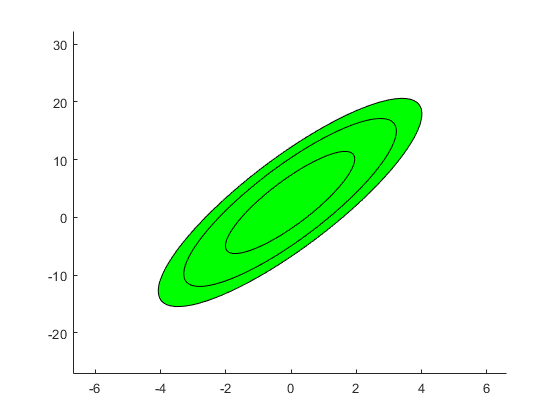

tt = 4;
meshdx = 0.1;
mu = x_prior_m(:, tt)';
sigma = P_prior_m(:, 2*tt-1:2*tt);
x1 = mu(1)-5*sqrt(sigma(1, 1)):meshdx:mu(1)+5*sqrt(sigma(1, 1));
x2 = mu(2)-5*sqrt(sigma(2, 2)):meshdx:mu(2)+5*sqrt(sigma(2, 2));
[X1, X2] = meshgrid(x1, x2);
XX = [X1(:) X2(:)];
ZZ = mvnpdf(XX, mu, sigma);
ZZ = reshape(ZZ, length(x2), length(x1));
ps = [0.67, 0.95, 0.99];
levels = nan(length(ps), 1);
for ii = 1 : length(ps)
    s = -2 * log(1 - ps(ii)); % == icdf('Chi', p , nx) % nx=2 degrees of freedom
    [V, D] = eig(sigma * s);
    t = linspace(0, 2 * pi);
    a = (V * sqrt(D)) * [cos(t(:))'; sin(t(:))'];
    xx = a(1, :) + mu(1);
    yy = a(2, :) + mu(2);
    zz = mvnpdf([xx' yy'], mu, sigma);
    levels(ii) = zz(1);
end
figure(); hold on;
cc = contourf(X1, X2, ZZ, levels);
colormap([[0 1 0]; [0 1 0]; [0 1 0]]);
alphamap([0.1, 0.4, 0.8])

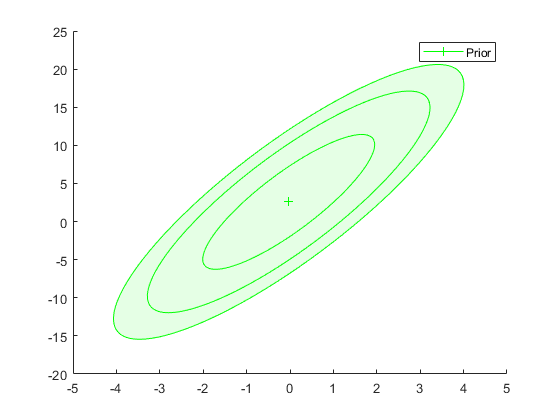

figure; hold on;
legend('location', 'northeast');
plot_covariance_ellipse_alt(mu, sigma, [0.67, 0.95, 0.99], 'g', 0.1, ['Prior ']);

%xlim([-5, 15]); ylim([-10, 15])

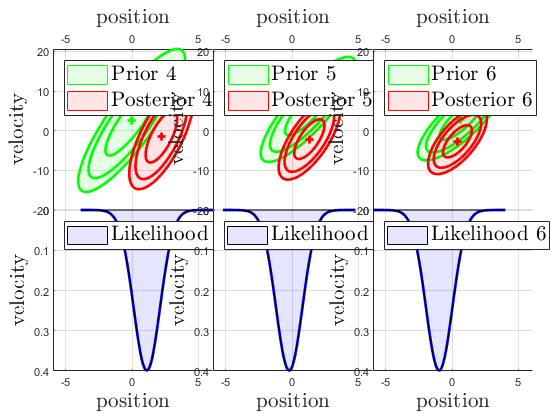

% Relationship posterior - prior - posterior
% t = tiledlayout(1, 2, 'TileSpacing', "compact", "Padding", "compact", Units="centimeters", OuterPosition=[0 0 width, width/AR]);
t = tiledlayout(2, 3, 'TileSpacing', 'none', "Padding", "compact", 'TileIndexing', 'columnmajor');
%xlabel(t, 'Time [ms]', 'Interpreter', "latex", 'FontSize', 16)
%ylabel(t, 'Current profile [mA]', 'Interpreter', "latex", 'FontSize', 16)

ax1 = nexttile(1); hold on; grid on;
tt = 4;
xlabel('position', 'Interpreter', 'latex', 'FontSize', 16); ylabel('velocity', 'Interpreter', 'latex', 'FontSize', 16); legend('location', 'northwest', 'Interpreter', 'latex', 'FontSize', 16);
plot_covariance_ellipse_alt(x_prior_m(:, tt), P_prior_m(:, 2*tt-1:2*tt), [0.67, 0.95, 0.99], 'g', 0.1, ['Prior ' num2str(tt)]);
%plot_covariance_ellipse(x_prior_m(:, tt), P_prior_m(:, 2*tt-1:2*tt), 0.67, 'g', ['Prior ' num2str(tt)]);
plot_covariance_ellipse_alt(x_posterior_m(:, tt), P_posterior_m(:, 2*tt-1:2*tt), [0.67, 0.95, 0.99], 'r', 0.1, ['Posterior ' num2str(tt)]);
%plot_covariance_ellipse(x_posterior_m(:, tt), P_posterior_m(:, 2*tt-1:2*tt), 0.67, 'r', ['Posterior ' num2str(tt)]);
ax1.XAxisLocation = 'top';

ax2 = nexttile(2); hold on; grid on;
xlabel('position', 'Interpreter', 'latex', 'FontSize', 16); ylabel('velocity', 'Interpreter', 'latex', 'FontSize', 16); legend('location', 'northwest', 'Interpreter', 'latex', 'FontSize', 16);
dx = 0.1;
mu = measures{tt};
sigma = R;
x = mu-5*sqrt(sigma):dx:mu+5*sqrt(sigma);
y = normpdf(x, mu, sigma);
hp2 = plot(x, y, 'b', 'LineWidth', 2);
hp2.Annotation.LegendInformation.IconDisplayStyle = 'off';
fill(x, y, 'b', 'FaceAlpha', 0.1, 'displayname', ['Likelihood ' num2str(tt)])
ax2.YDir = 'reverse';

ax3 = nexttile(3); hold on; grid on;
tt = 5;
xlabel('position', 'Interpreter', 'latex', 'FontSize', 16); ylabel('velocity', 'Interpreter', 'latex', 'FontSize', 16); legend('location', 'northwest', 'Interpreter', 'latex', 'FontSize', 16);
plot_covariance_ellipse_alt(x_prior_m(:, tt), P_prior_m(:, 2*tt-1:2*tt), [0.67, 0.95, 0.99], 'g', 0.1, ['Prior ' num2str(tt)]);
%plot_covariance_ellipse(x_prior_m(:, tt), P_prior_m(:, 2*tt-1:2*tt), 0.67, 'g', ['Prior ' num2str(tt)]);
plot_covariance_ellipse_alt(x_posterior_m(:, tt), P_posterior_m(:, 2*tt-1:2*tt), [0.67, 0.95, 0.99], 'r', 0.1, ['Posterior ' num2str(tt)]);
%plot_covariance_ellipse(x_posterior_m(:, tt), P_posterior_m(:, 2*tt-1:2*tt), 0.67, 'r', ['Posterior ' num2str(tt)]);
ax3.XAxisLocation = 'top';

ax4 = nexttile(4); hold on; grid on;
xlabel('position', 'Interpreter', 'latex', 'FontSize', 16); ylabel('velocity', 'Interpreter', 'latex', 'FontSize', 16); legend('location', 'northwest', 'Interpreter', 'latex', 'FontSize', 16);
dx = 0.1;
mu = measures{tt};
sigma = R;
x = mu-5*sqrt(sigma):dx:mu+5*sqrt(sigma);
y = normpdf(x, mu, sigma);
hp4 = plot(x, y, 'b', 'LineWidth', 2);
hp4.Annotation.LegendInformation.IconDisplayStyle = 'off';
fill(x, y, 'b', 'FaceAlpha', 0.1, 'displayname', ['Likelihood ' num2str(tt)])
ax4.YDir = 'reverse';

ax5 = nexttile(5); hold on; grid on;
tt = 6;
xlabel('position', 'Interpreter', 'latex', 'FontSize', 16); ylabel('velocity', 'Interpreter', 'latex', 'FontSize', 16); legend('location', 'northwest', 'Interpreter', 'latex', 'FontSize', 16);
plot_covariance_ellipse_alt(x_prior_m(:, tt), P_prior_m(:, 2*tt-1:2*tt), [0.67, 0.95, 0.99], 'g', 0.1, ['Prior ' num2str(tt)]);
%plot_covariance_ellipse(x_prior_m(:, tt), P_prior_m(:, 2*tt-1:2*tt), 0.67, 'g', ['Prior ' num2str(tt)]);
plot_covariance_ellipse_alt(x_posterior_m(:, tt), P_posterior_m(:, 2*tt-1:2*tt), [0.67, 0.95, 0.99], 'r', 0.1, ['Posterior ' num2str(tt)]);
%plot_covariance_ellipse(x_posterior_m(:, tt), P_posterior_m(:, 2*tt-1:2*tt), 0.67, 'r', ['Posterior ' num2str(tt)]);
ax5.XAxisLocation = 'top';

ax6 = nexttile(6); hold on; grid on;
xlabel('position', 'Interpreter', 'latex', 'FontSize', 16); ylabel('velocity', 'Interpreter', 'latex', 'FontSize', 16); legend('location', 'northwest', 'Interpreter', 'latex', 'FontSize', 16);
dx = 0.1;
mu = measures{tt};
sigma = R;
x = mu-5*sqrt(sigma):dx:mu+5*sqrt(sigma);
y = normpdf(x, mu, sigma);
hp6 = plot(x, y, 'b', 'LineWidth', 2);
hp6.Annotation.LegendInformation.IconDisplayStyle = 'off';
fill(x, y, 'b', 'FaceAlpha', 0.1, 'displayname', ['Likelihood ' num2str(tt)])
ax6.YDir = 'reverse';

linkaxes([ax1, ax2, ax3, ax4, ax5, ax6], 'x')
linkaxes([ax1, ax3, ax5], 'y')
linkaxes([ax2, ax4, ax6], 'y')
%xlim([0, 5]); ylim([-5, 15]); % custom view
exportgraphics(gcf, 'KFiters.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector')

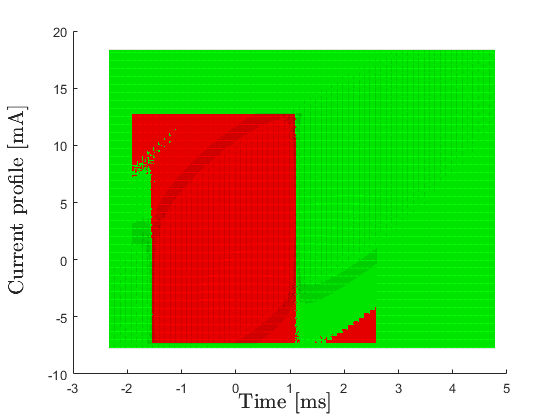

figure(); hold on;
meshdx = 0.1;
iter = 5;
mu = x_prior_m(:, iter)';
sigma = P_prior_m(:, 2*iter-1:2*iter)';
x1 = mu(1)-3*sqrt(sigma(1, 1)):meshdx:mu(1)+3*sqrt(sigma(1, 1));
x2 = mu(2)-3*sqrt(sigma(2, 2)):meshdx:mu(2)+3*sqrt(sigma(2, 2));
[X1, X2] = meshgrid(x1, x2);
XX = [X1(:) X2(:)];
ZZ = mvnpdf(XX, mu, sigma);
ZZ = reshape(ZZ, length(x2), length(x1));
%surf(X1, X2, ZZ, 'FaceColor', 'r', 'FaceAlpha', 0.5, 'EdgeColor', 'none')
surf(X1, X2, ZZ, 'FaceColor', 'g', 'EdgeAlpha', 0.1)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% mu = (H*x_prior_m(:, 5))';
% sigma = S_m(:, 9:10)';
% x1 = mu(1)-3*sqrt(sigma(1, 1)):meshdx:mu(1)+3*sqrt(sigma(1, 1));
% x2 = mu(2)-3*sqrt(sigma(2, 2)):meshdx:mu(2)+3*sqrt(sigma(2, 2));
% [X1, X2] = meshgrid(x1, x2);
% XX = [X1(:) X2(:)];
% ZZ = mvnpdf(XX, mu, sigma);
% ZZ = reshape(ZZ, length(x2), length(x1));
% %surf(X1, X2, ZZ, 'FaceColor', 'b', 'FaceAlpha', 0.5, 'EdgeColor', 'none')
% surf(X1, X2, ZZ, 'FaceColor', 'r', 'EdgeAlpha', 0.1)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mu = x_posterior_m(:, iter)';
sigma = P_posterior_m(:, 2*iter-1:2*iter)';
x1 = mu(1)-3*sqrt(sigma(1, 1)):meshdx:mu(1)+3*sqrt(sigma(1, 1));
x2 = mu(2)-3*sqrt(sigma(2, 2)):meshdx:mu(2)+3*sqrt(sigma(2, 2));
[X1, X2] = meshgrid(x1, x2);
XX = [X1(:) X2(:)];
ZZ = mvnpdf(XX, mu, sigma);
ZZ = reshape(ZZ, length(x2), length(x1));
%surf(X1, X2, ZZ, 'FaceColor', 'b', 'FaceAlpha', 0.5, 'EdgeColor', 'none')
surf(X1, X2, ZZ, 'FaceColor', 'r', 'EdgeAlpha', 0.1)

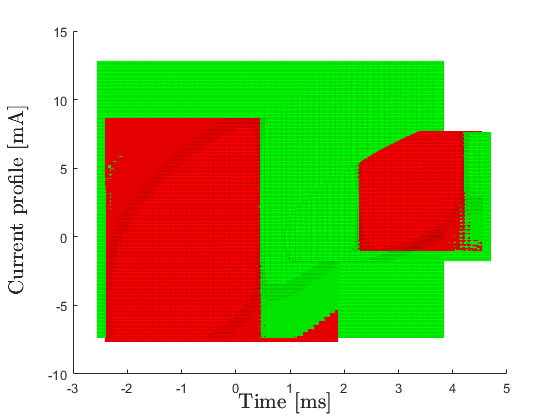

figure(); hold on;
meshdx = 0.1;
iter = 6;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mu = x_prior_m(:, iter)';
sigma = P_prior_m(:, 2*iter-1:2*iter)';
x1 = mu(1)-3*sqrt(sigma(1, 1)):meshdx:mu(1)+3*sqrt(sigma(1, 1));
x2 = mu(2)-3*sqrt(sigma(2, 2)):meshdx:mu(2)+3*sqrt(sigma(2, 2));
[X1, X2] = meshgrid(x1, x2);
XX = [X1(:) X2(:)];
ZZ = mvnpdf(XX, mu, sigma);
ZZ = reshape(ZZ, length(x2), length(x1));
%surf(X1, X2, ZZ, 'FaceColor', 'r', 'FaceAlpha', 0.5, 'EdgeColor', 'none')
surf(X1, X2, ZZ, 'FaceColor', 'g', 'EdgeAlpha', 0.1)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mu = x_posterior_m(:, iter)';
sigma = P_posterior_m(:, 2*iter-1:2*iter)';
x1 = mu(1)-3*sqrt(sigma(1, 1)):meshdx:mu(1)+3*sqrt(sigma(1, 1));
x2 = mu(2)-3*sqrt(sigma(2, 2)):meshdx:mu(2)+3*sqrt(sigma(2, 2));
[X1, X2] = meshgrid(x1, x2);
XX = [X1(:) X2(:)];
ZZ = mvnpdf(XX, mu, sigma);
ZZ = reshape(ZZ, length(x2), length(x1));
%surf(X1, X2, ZZ, 'FaceColor', 'r', 'FaceAlpha', 0.5, 'EdgeColor', 'none')
surf(X1, X2, ZZ, 'FaceColor', 'r', 'EdgeAlpha', 0.1)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
iter = 12;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mu = x_prior_m(:, iter)';
sigma = P_prior_m(:, 2*iter-1:2*iter)';
x1 = mu(1)-3*sqrt(sigma(1, 1)):meshdx:mu(1)+3*sqrt(sigma(1, 1));
x2 = mu(2)-3*sqrt(sigma(2, 2)):meshdx:mu(2)+3*sqrt(sigma(2, 2));
[X1, X2] = meshgrid(x1, x2);
XX = [X1(:) X2(:)];
ZZ = mvnpdf(XX, mu, sigma);
ZZ = reshape(ZZ, length(x2), length(x1));
%surf(X1, X2, ZZ, 'FaceColor', 'r', 'FaceAlpha', 0.5, 'EdgeColor', 'none')
surf(X1, X2, ZZ, 'FaceColor', 'g', 'EdgeAlpha', 0.1)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mu = x_posterior_m(:, iter)';
sigma = P_posterior_m(:, 2*iter-1:2*iter)';
x1 = mu(1)-3*sqrt(sigma(1, 1)):meshdx:mu(1)+3*sqrt(sigma(1, 1));
x2 = mu(2)-3*sqrt(sigma(2, 2)):meshdx:mu(2)+3*sqrt(sigma(2, 2));
[X1, X2] = meshgrid(x1, x2);
XX = [X1(:) X2(:)];
ZZ = mvnpdf(XX, mu, sigma);
ZZ = reshape(ZZ, length(x2), length(x1));
%surf(X1, X2, ZZ, 'FaceColor', 'b', 'FaceAlpha', 0.5, 'EdgeColor', 'none')
surf(X1, X2, ZZ, 'FaceColor', 'r', 'EdgeAlpha', 0.1)

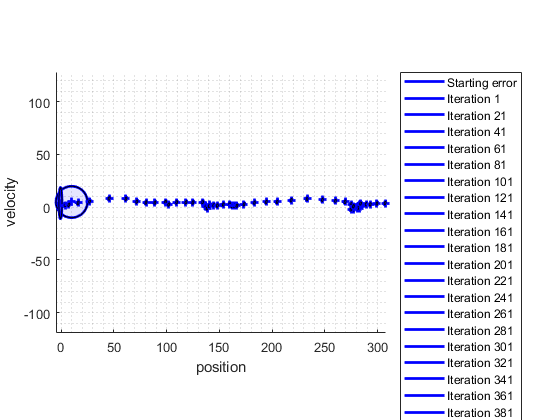

% Posterior convergence
figure; hold on; grid minor;
set(gcf, 'DefaultLineLineWidth', 2);
axis equal; xlabel('position'); ylabel('velocity'); legend('location', 'eastoutside');
plot_covariance_ellipse(x0, P0, 0.67, 'b', 'Starting error');
for tt = 1 : 20 : iterations
    plot_covariance_ellipse(x_posterior_m(:, tt), P_posterior_m(:, 2*tt-1:2*tt), 0.67, 'b', ['Iteration ' num2str(tt)]);
end

### **Residuals analysis**

e_m = cell2mat(residuals);
mean(e_m)

ans = -0.0060

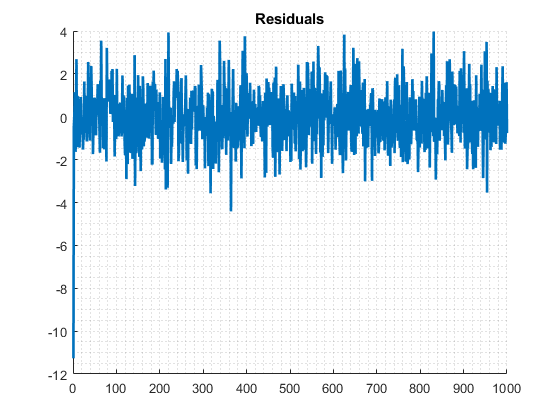

figure; hold on; grid minor;
set(gcf, 'DefaultLineLineWidth', 2);
plot(e_m)
title('Residuals')

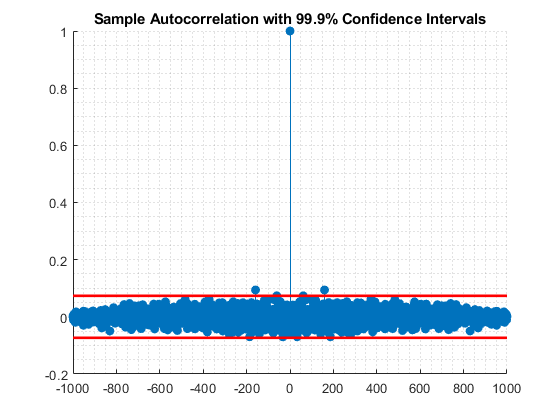

% https://www.mathworks.com/help/signal/ug/residual-analysis-with-autocorrelation.html
[xc, lags] = xcorr(e_m, iterations, 'coeff');
confidence_value = 0.999;
conf = sqrt(2) * erfcinv(2*(1-confidence_value)/2);
lconf = -conf/sqrt(length(xc));
upconf = conf/sqrt(length(xc));
figure; hold on; grid minor;
stem(lags, xc, 'filled')
plot(lags, lconf*ones(size(lags)), 'r', 'LineWidth', 2)
plot(lags, upconf*ones(size(lags)), 'r', 'LineWidth', 2)
title('Sample Autocorrelation with 99.9% Confidence Intervals')

### **MATLAB Kalman filter**

D = 0;
G = eye(2);
V = [0, 0];
sys = ss(F, [B, G], H, [D, V], dt);
[KEST, K_bar, P_bar, M, Z] = kalman(sys, Q, R, 'current');

### **Asintotic Filtering**

% initialization
x = x0;

for tt = 1 : iterations
    % predict step:
    x = F*x + B*u;
    
    % update step:
    % (code writable in one line)
    z = measures{tt};
    e = z - H*x;
    K = M;
    x = x + K*e;
    
    % saving
    x_posterior{tt} = x;
end

### **Asintotic Plot**

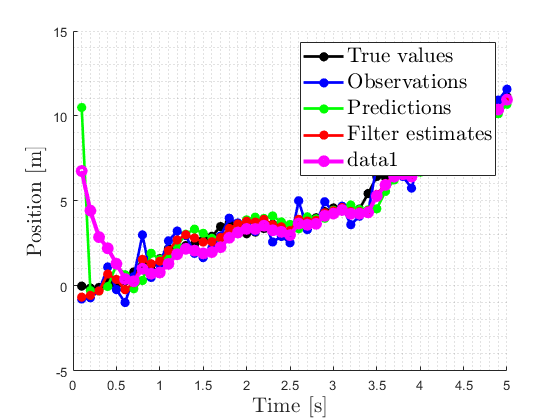

% data
x_posterior_m = cell2mat(x_posterior);

% compare position
figure(1);
plot(time, x_posterior_m(1, :), 'm-o', 'LineWidth', 3)